# **RRA**

# **Lab8 (Parteneriat cu laburile scrise de PETrascu)**

## **Algoritmi numerici pentru EMAR**

Noi la **Control Optimal (CO)** am invatat pentru EMAR 3 solutii prin care putem calcula solutia:

- Metoda Vectorilor Schur

- Metoda Newton-Kleinman

- Metoda Sign-Matrix

Noi de obicei uitam sa lucram cu matricea Hamilton, pentru ca avem $R^{-1}$. Daca acest **R nu este bine conditionat,** atunci sa lucrezi cu matricea Hamilton poate fi o provocare **urata**. Asadar, prefeream sa lucram cu **Fasciculul Hamiltonian extins**

Fie 2 matrici $M,N\in {\mathbb{R}}^{n\times n}$. Se numeste Fascilul matriceal o matrice polinomiala de gradul 1 $\textrm{sM}-N$ in valrabila s. 

Acest fascicul (pencil in engleza) este **regulat** cand $\det \left(\textrm{sM}-N\right)\not\equiv 0$. Mai poate fi regulat cand $M\;\textrm{sau}\;N$ sunt inversabile.

Daca un fascicol este regulat, atunci paote avea matricile $M\;\textrm{si}\;N$ singulare.

#### Problema de Valori Proprii (Generealizate) (V.P.(G)): 


$$\chi \left(s\right):=\det \left(\textrm{sM}-N\right)=0,s\in \mathbb{C}$$


Cum $M$ poate fi singular, polinomul caracteristic $\chi$ are gradul $n_f \le n$

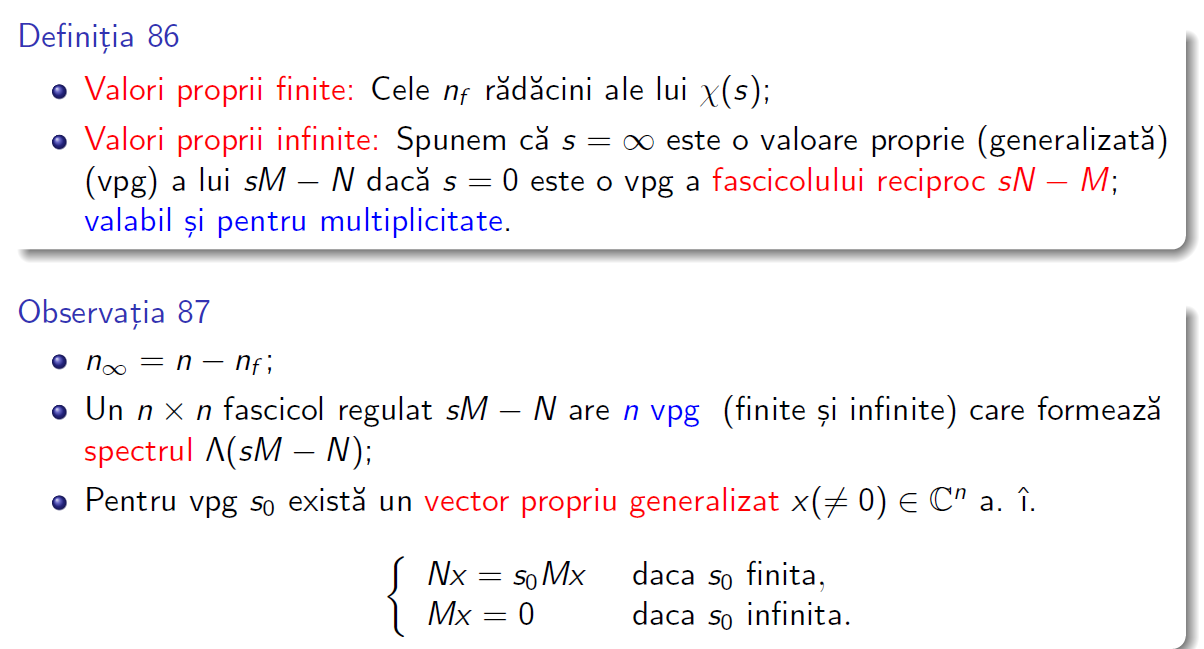

#### Azi tratam cazul de fasciol regulat

Fascicolul de 0-uri al $\textrm{SH}\left(\Sigma \right)$ se numeste **Fascicul Hamiltonian (Extins) **$\textrm{FH}\left(\Sigma \right)$. Cum arata acesta?

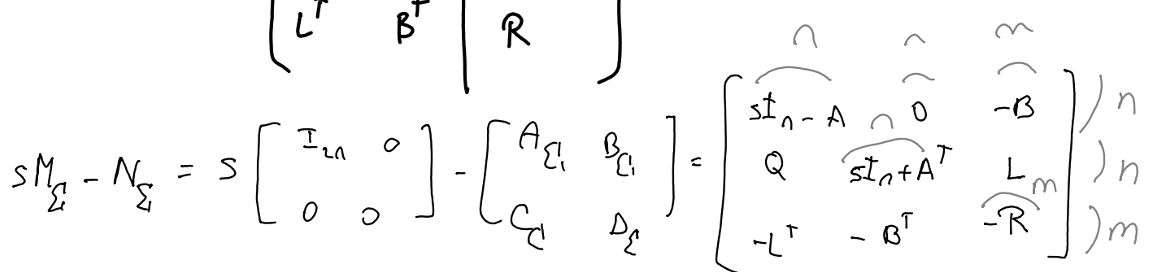

Daca $R$ este inversabil, atunci **Fascicolul Hamiltonian Extins (Extended Hamiltonian Pencil) este regulat**.

Fie 2 fascicole $\left\lbrace \begin{array}{l}
\textrm{sM}-N\\
s\tilde{M} -\tilde{N} 
\end{array}\right.$, cu $M,N,\tilde{M} ,\tilde{N} \in {\mathbb{C}}^{m\times n}$. Aceste 2 fascicole sunt (strict) echivalente daca $\exists$ doua matrici **constante si inversabile **$Q\in {\mathbb{C}}^{m\times m} \textrm{si}\;Z\in {\mathbb{C}}^{n\times n}$ astfel incat $Q\left(\textrm{sM}-N\right)Z=s\tilde{M} -\tilde{N}$.

Pentru orice fascicol $\textrm{sM}-N,\textrm{cu}\;M,N\in {\mathbb{C}}^{n\times n}$ exista 2 matrici $Q,Z\in {\mathbb{C}}^{n\times n}$astfel incat 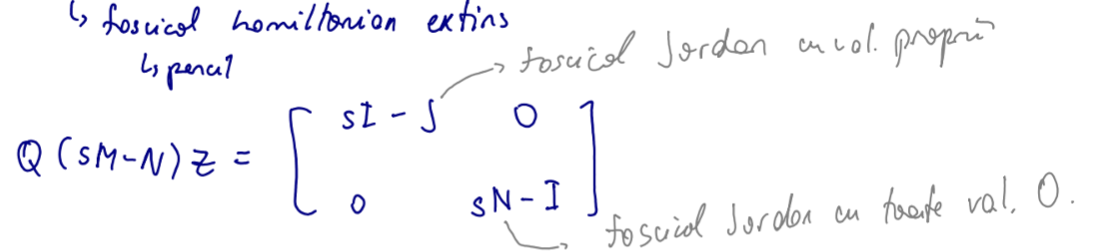, care este o forma canonica Weierstrass, unde $\left\lbrace \begin{array}{l}
J\;\textrm{este}\;\textrm{forma}\;\textrm{canonica}\;\textrm{Jordan}\;\textrm{cu}\;\textrm{valori}\;\textrm{proprii}\\
N\;\textrm{este}\;\textrm{forma}\;\textrm{canonica}\;\textrm{Jordan}\;\textrm{cu}\;\textrm{toate}\;\textrm{valorile}\;\textrm{proprii}\;0
\end{array}\right.$

Acum intram in ceva nasol

## Spatiu de deflatie:

Fie $\textrm{sM}-N$ un fascicol regulat cu $M,N\in {\mathbb{C}}^{n\times n}$. Spatul liniar $\mathcal{V}\in {\mathbb{C}}^n$ se numeste spatiu de deflatie daca $\dim \left(M\mathcal{V}\oplus N\mathcal{V}\right)=\dim \mathcal{V}$ (numar de elemente din baza).

Putem sa aratam ca exista o matrice pentru care $\mathcal{V}=\mathrm{Im}\;Z_1 \to Z_1 \in {\mathbb{R}}^{n\times l}$ are rang intreg pe coloane.

**Pana sa trecem mai departe, o sa definesc 2 chestii: Produsul dintre M si **$\mathcal{V}$ $M\mathcal{V}=\left\lbrace \textrm{Mx}|x\in \mathcal{V}\right\rbrace$**. Aceesi logica este si la produsul dintre N si **$\mathcal{V}$**. De asemenea, mai definim suma Minkowsky (Minkowsky sum) **$X\oplus Y=\left\lbrace x+y|x\in X,y\in Y\right\rbrace$

Sa notam $\mathcal{W}=$$\left(M\mathcal{V}\oplus N\mathcal{V}\right)$. Daca $\mathcal{V}\in {\mathbb{C}}^n$ este un spatiu (nu neaparat de deflatie) de dimensiune l, atunci $\dim \;\mathcal{W}\ge \dim \;\mathcal{V}=l$ (egalitatea are loc daca $\mathcal{V}$ est spatiu de deflatie).

Un caz particular este acela cand $M=I$. Asadar, o sa avem fascicolul $\textrm{sI}-N$, iar $W:=\mathcal{V}\oplus N\mathcal{V}$, iar $\dim \;\mathcal{W}=\dim \;\mathcal{V}\Leftrightarrow N\mathcal{V}\supseteq \mathcal{V}$, unde $\mathcal{V}$ este un subspatiu $N-\textrm{invariant}$.

#### Pe noi ne intereseaza spatiile invariante. De ce ? Noi cand faceam blocuri la Schur, lucram cu subspatii invariante

$H={\textrm{USU}}^T =\left\lbrack \begin{array}{cc}
U_{11}  & U_{12} \\
U_{21}  & U_{22} 
\end{array}\right\rbrack \left\lbrack \begin{array}{cc}
S_{11}  & S_{12} \\
0 & S_{22} 
\end{array}\right\rbrack {\left\lbrack \begin{array}{cc}
U_{11}  & U_{12} \\
U_{21}  & U_{22} 
\end{array}\right\rbrack }^T$, unde $\Lambda \left(S_{11} \right)\in {\mathbb{C}}_-$$\hookleftarrow$


$$H\left\lbrack \begin{array}{c}
U_{11} \\
U_{12} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
U_{11} \\
U_{12} 
\end{array}\right\rbrack S_{11}$$

$$\hookleftarrow$$


$\mathcal{V}=\textrm{lm}\left\lbrack \begin{array}{c}
U_{11} \\
U_{12} 
\end{array}\right\rbrack$. Ceva interesant: se poate vedea ca este un spatiu invariant asociat cu un spectru stabil. Ceva de gen vrem sa facem si la fascicolul nostru regulat.

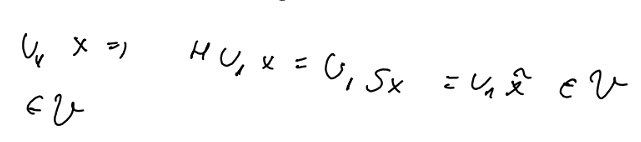

Fie $\left\lbrace \begin{array}{l}
\mathcal{V}\in \textrm{Im}\;Z_1 \\
\mathcal{W}\in \textrm{Im}\;Q_1 
\end{array}\right.$. Constuim matricile $Q\;\textrm{si}\;Z$ astfel: $\left\lbrace \begin{array}{l}
Q=\left\lbrack \begin{array}{cc}
Q_1  & Q_2 
\end{array}\right\rbrack \\
Z=\left\lbrack \begin{array}{cc}
Z_1  & Z_2 
\end{array}\right\rbrack 
\end{array}\right.$, unde $\left\lbrace \begin{array}{l}
Q_2 \\
Z_2 
\end{array}\right.$ sunt completari pana cand matricile $Q,Z$ sunt inversabile.

Stim ca $\left\lbrace \begin{array}{l}
M\mathcal{V}\in {\mathcal{V}}^{\prime } \\
N\mathcal{V}\in {\mathcal{V}}^{\prime } 
\end{array}\right.$. Atunci $Q^{-1} \left(\mathrm{sM}-N\right)Z=\left\lbrack \begin{array}{cc}
{\mathrm{sM}}_{11} -N_{11}  & {\mathrm{sM}}_{12} -N_{12} \\
0 & {\mathrm{sM}}_{22} -N_{22} 
\end{array}\right\rbrack$

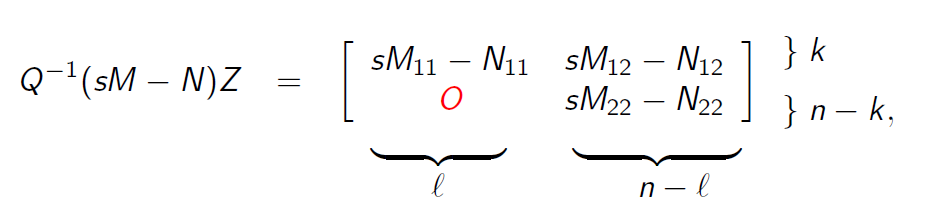

unde $k\ge l$. In acest nou sistem de coordonate $\mathcal{V}\;\mathrm{si}\;\mathcal{W}$ se reprezinta: $\left\lbrace \begin{array}{l}
\mathcal{V}=\mathrm{Im}\left\lbrack \begin{array}{c}
I_l \\
0
\end{array}\right\rbrack \\
\mathcal{W}=\mathrm{Im}\left\lbrack \begin{array}{c}
I_k \\
0
\end{array}\right\rbrack 
\end{array}\right.$

In cazul in care $k=l$, adica folosim spatiu de deflatie $\left(\dim \;\mathcal{W}=k=l=\dim \mathcal{V}\right)$, atunci $\Lambda \left(\mathrm{sM}-N\right)=\Lambda \left({\mathrm{sM}}_{11} -N_{11} \right)\cup \Lambda \left({\mathrm{sM}}_{22} -N_{22} \right)$

Daca $\mathrm{Im}\;Z_1 =\mathcal{V}$ si $k=l$, atunci $\Lambda \left(\mathrm{sM}-N\right)|_{\mathcal{V}} =\Lambda \left({\mathrm{sM}}_{11} -N_{11} \right)\Rightarrow$$\mathrm{sM}-N|_{\mathcal{V}} ={\mathrm{sM}}_{11} -N_{11}$. $\mathrm{sM}-N|_{\mathcal{V}}$ este notatie la fascicolul $\mathrm{sM}-N$ restrictionat de $\mathcal{V}$.

Sa impartim multimea numerelor complexe in 2 parti: o parte "buna" si alta "rea". Mai specific, $\mathbb{C}={\mathbb{C}}_g \bigcup {\mathbb{C}}_b$, cu ${\mathbb{C}}_g \bigcap {\mathbb{C}}_b =\left\lbrace \phi \right\rbrace$, adica multimea vida. Ce inseamna acest bun si rau? Depinde strict de problema noastra de control robust.

Un spatiu de deflatie $\mathcal{V}$ este ${\mathbb{C}}_g -$deflatie daca $\Lambda \left(\mathrm{sM}-N\right)|_{\mathcal{V}} \in {\mathbb{C}}_g$

Fie fascicolul regulat $\mathrm{sM}-N$.Atunci:

- Daca $\mathcal{V}\in {\mathbb{R}}^n$ este un spatiu de deflatie $l-\mathrm{dimensional}$ si $\mathcal{W}=M\mathcal{V}\oplus N\mathcal{V}$, atunci $\exists \left\lbrace \begin{array}{l}
Z=\left\lbrack \begin{array}{cc}
Z_1  & Z_2 
\end{array}\right\rbrack \\
Q=\left\lbrack \begin{array}{cc}
Q_1  & Q_2 
\end{array}\right\rbrack 
\end{array}\right.$ cu $\left\lbrace \begin{array}{l}
\mathcal{V}=\mathrm{Im}\;Z_1 \\
\mathcal{W}=\mathrm{Im}Q_1 
\end{array}\right.$ a.i $\left\lbrace \begin{array}{l}
Q^{-1} \left(\mathrm{sM}-N\right)Z=\left\lbrack \begin{array}{cc}
{\mathrm{sM}}_{11} -N_{11}  & {\mathrm{sM}}_{12} -N_{12} \\
0 & {\mathrm{sM}}_{22} -N_{22} 
\end{array}\right\rbrack \\
{\mathrm{sM}}_{11} -N_{11} =\mathrm{sM}-N|_{\mathcal{V}} 
\end{array}\right.\;\left(*\right)$

- Daca ecuatia de la $\left(*\right)$ tine pentru 2 matrici $Z=\left\lbrack \begin{array}{cc}
Z_1  & Z_2 
\end{array}\right\rbrack$ si $Q=\left\lbrack \begin{array}{cc}
Q_1  & Q_2 
\end{array}\right\rbrack$, atunci $\mathcal{V}\in \mathrm{Im}\;Z_1$ este un subspatiu de delfatie al fascicolului $\mathrm{sM}-N$, $\mathcal{W}=\mathrm{Im}\;Q_1$, unde $\mathcal{W}:=M\mathcal{V}\oplus N\mathcal{V}$ si ${\mathrm{sM}}_{11} -N_{11} =\mathrm{sM}-N|_{\mathcal{V}}$

Daca fascicolul $\mathrm{sM}-N$ este regulat si $\mathcal{V}$ este un spatou de deflatie pentru $\mathrm{sM}-N$ si tine $\left(*\right)$, atunci

- $M,N\in {\mathbb{R}}^{n\times n}$ si $\Lambda \left(\mathrm{sM}-N\right)|_{\mathcal{V}}$ este simetric, atunci $\mathcal{V}$ poate fi ales mereu in ${\mathbb{R}}^{n\times n}$

- Daca $\Lambda \left({\mathrm{sM}}_{11} -N_{11} \right)\cap \Lambda \left({\mathrm{sM}}_{22} -N_{22} \right)=\phi$, adica multimea vida, autnci $\mathcal{V}$ este unic in ${\mathbb{R}}^{n\times n}$

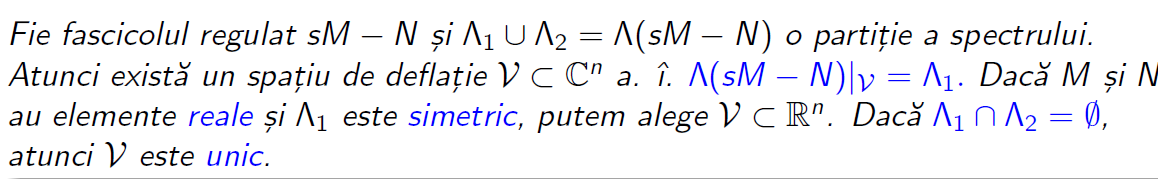

Fie $\left\lbrack \begin{array}{c}
B_{11} \\
B_{21} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
B_{21} \\
B_{22} 
\end{array}\right\rbrack S$: $B_1 =B_2 S$. $S$ este inversabila automat cand $B_1 \;\mathrm{si}\;B_2$ sunt baze: preactic matrici de transfer de la o baza la alta.

### Reamintire:

Fascicolul de 0-uri al $\textrm{SH}\left(\Sigma \right)$ se numeste **Fascicul Hamiltonian (Extins) **$\textrm{FH}\left(\Sigma \right)$. Cum arata acesta?

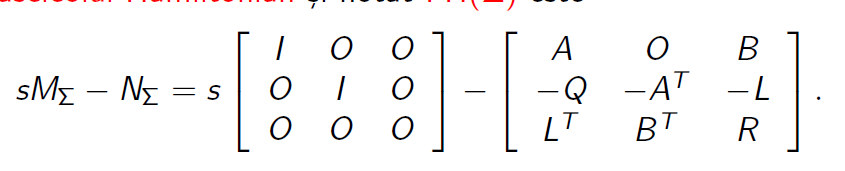

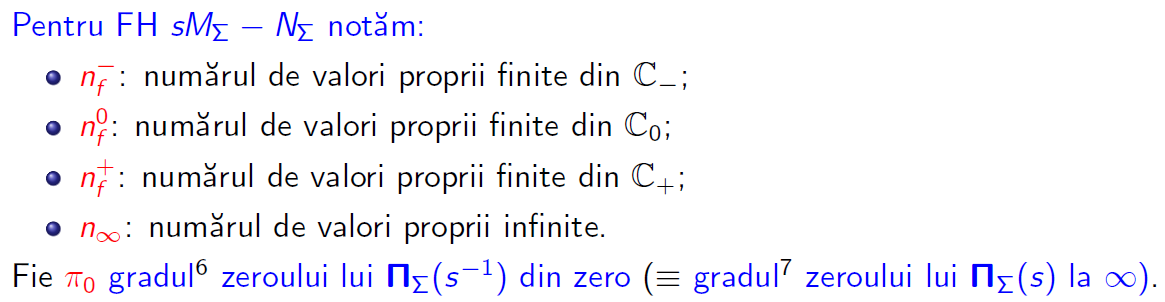

Daca $\mathrm{EHP}\left(\Sigma \right)$ este regulat,atunci $n_f^- =n_f^+ \;\mathrm{si}\;n_{\infty } =m+\pi_0$, unde $\pi_0$ este suma gradelor partiale ale lui 0 ca zero pentru $\prod_{\Sigma } \left(\frac{1}{s}\right)$. Facem chestia aia ca daca ne este greu sa ne uitam la infinit la $\prod_{\Sigma } \left(s\right)$, ne uitam la zero prin schimbul $s\to \frac{1}{s}$. In plus, rangul normal ${\mathrm{rang}}_n \left(\prod_{\Sigma } \left(s\right)\right)=n$. Daca R este inversabila, atunci $\mathrm{rank}\left(R\right)=n\Rightarrow \pi_0 =0$

Un **Fascicol Hamiltonian (FH)** este *dihotomic* daca $n_f^0 =0\;\mathrm{si}\;n_{\infty } =m$, sau echivalent $\pi_0 =0$

Daca $\mathrm{EHP}\left(\Sigma \right)$ are un spatiu de ${\mathbb{C}}_- -\mathrm{deflatie}$ de dimensiune n, atunci acesta este maximal, adica nu am cum sa am un spatiu de ${\mathbb{C}}_- -\mathrm{deflatie}$ cu dimensiune > n.

Daca $\textrm{EHP}\left(\Sigma \right)$ are un spatiu de ${\mathbb{C}}_- -\mathrm{deflatie}$ $V=\mathrm{Im}\left\lbrack \begin{array}{c}
V_1 \\
V_2 \\
V_3 
\end{array}\right\rbrack$,atunci

- 
$$V_1^T V_2 =V_2^T V_1$$


- Daca in pkus $V_1$ are rang intreg pe coloane, atunci $V$ este disconjugat.

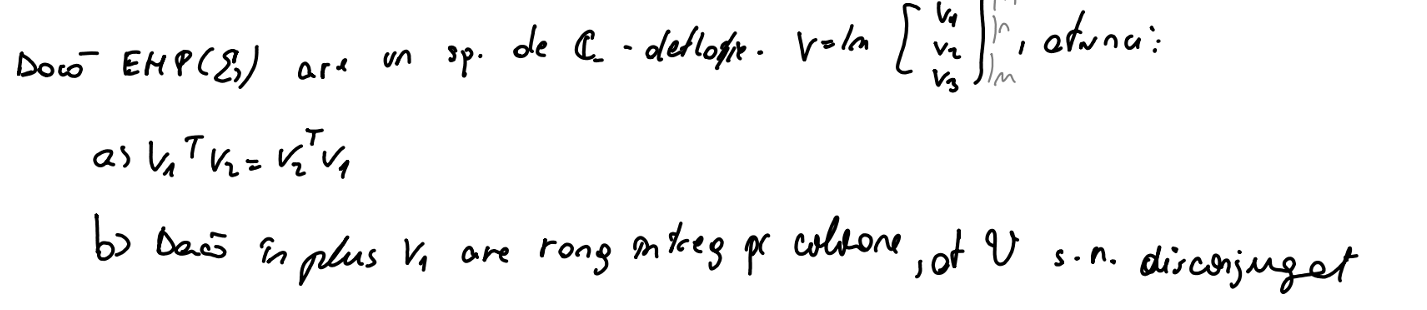

Fie $V$ spatiu de ${\mathbb{C}}_- -\mathrm{deflatie}$ maximal si disconjugat al $\mathrm{EHP}\left(\Sigma \right)$. Atunci $V_1$ este inversabil$\Rightarrow V_2 V_1^{-1} =V_1^{-T} V_2^T ={\left(V_2 V_1^{-1} \right)}^T$

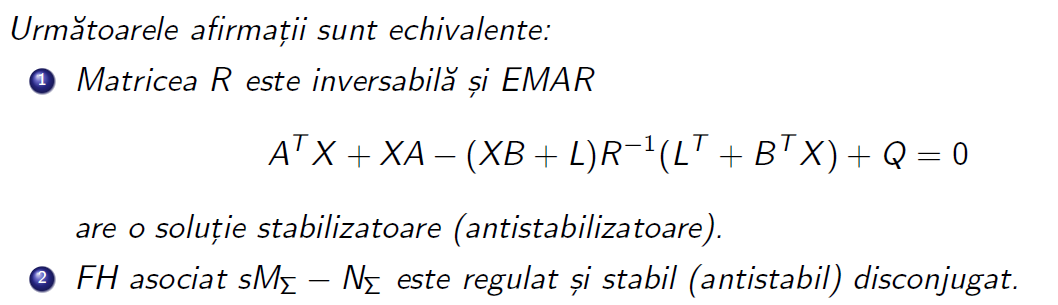

De asemenea, solutia si reactia Riccati sunt date de $\left\lbrace \begin{array}{l}
X=V_2 V_1^{-1} \\
F=V_3 V_1^{-1} 
\end{array}\right.$. Fun fact: Daca cumva $V_1$si $R_1$ nu este inversabil sau foarte prost conditionat, atunci ori nu exista $F_s$ sau este atat de prost numeric conditionat, incat nici nu merita sa fei calculat.

## Algoritmul QZ (Schur generalizat)

### Vreau mai intai sa vorbesc despre Forma Schur Generalizata

Forma Schur Generalizata este o alternativa numerica pentru Forma Canonica Weierstrass pentru un fascicol matriceal $\mathrm{sM}-N$. Este obtinut prin transformari unitare sau ortogonale echivalente (in mod specific QZ) si care dispun V.P.G pe diagonala principala

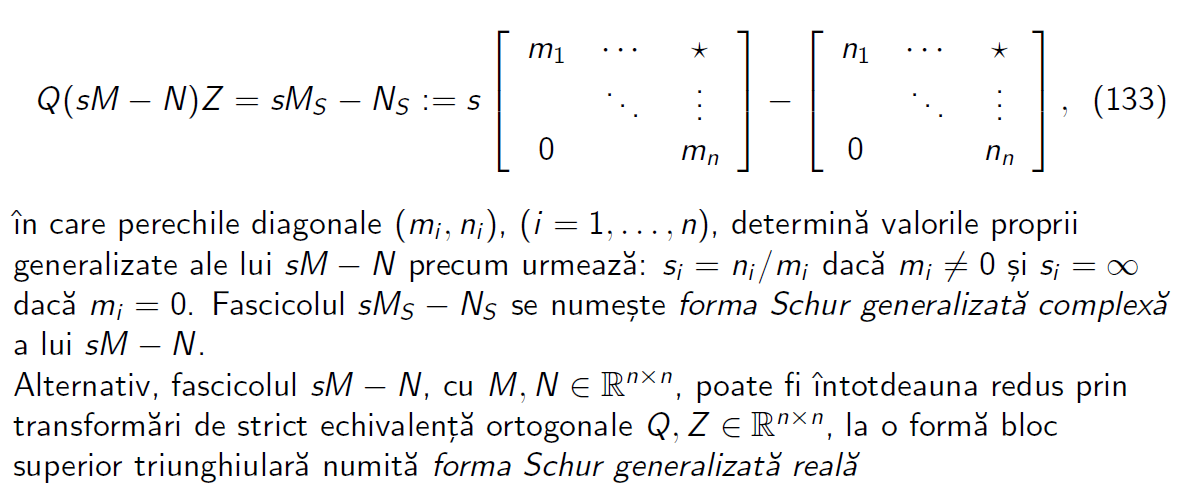


$$Q\left(\mathrm{sM}-N\right)Z={\mathrm{sM}}_{\Sigma } -N_{\Sigma } =s\left\lbrack \begin{array}{ccc}
M_{11}  & \ldots & M_{1k} \\
0 & \ddots  & \vdots \\
0 & 0 & M_{\mathrm{kk}} 
\end{array}\right\rbrack -\left\lbrack \begin{array}{ccc}
N_{11}  & \ldots & N_{1k} \\
0 & \ddots  & \vdots \\
0 & 0 & N_{\mathrm{kk}} 
\end{array}\right\rbrack$$


clear
close all
clc

Acum definesc A,B,Q,R,L

A = randn(4)

A =     1.0001    0.4227    0.0662    1.0061
   -1.6642   -1.6702    0.6524   -0.6509
   -0.5900    0.4716    0.3271    0.2571
   -0.2781   -1.2128    1.0826   -0.9444


B = randn(4,3)

B =    -1.3218    0.9111    0.9298
    0.9248    0.5946    0.2398
    0.0000    0.3502   -0.6904
   -0.0549    1.2503   -0.6516


Q = randn(4);

Q = Q * Q'

Q =     8.6505   -2.5629    5.4559    3.4250
   -2.5629    4.5779   -1.6240    1.0902
    5.4559   -1.6240    4.9767    5.4110
    3.4250    1.0902    5.4110    9.6404


R = randn(3);

R = R * R' + eye(3)

R =     2.5520   -0.6282    0.3072
   -0.6282    2.1775    0.1517
    0.3072    0.1517    1.5111


L = randn(4,3) * 1e-2

L =     0.0101   -0.0038   -0.0047
   -0.0212    0.0065    0.0014
   -0.0050    0.0083   -0.0029
   -0.0127   -0.0101    0.0030


Dupa ce am definit A,B,Q,R,L, acum vad daca am echivalenta aia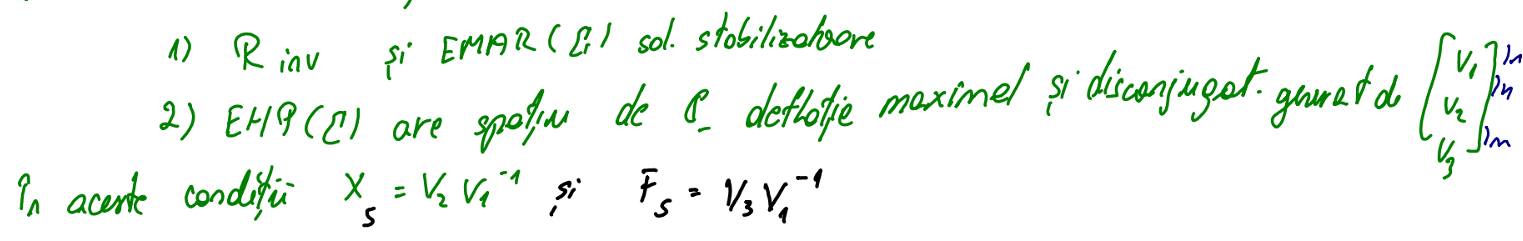

Rezolv Riccati cu icare

[X,F,spectru] = icare(A,B,Q,R,L)

X =     3.1361   -0.5479    1.1767    0.9890
   -0.5479    1.1648    0.0516   -0.4298
    1.1767    0.0516    3.5502    1.0808
    0.9890   -0.4298    1.0808    2.2348


F =    -1.6310    0.7440    0.0163   -0.1556
    1.3729    0.0783    1.8140    1.7779
    1.0694   -0.1488   -1.5432   -1.0619


spectru =   -0.3455 + 0.0000i
  -2.6824 + 0.0000i
  -3.9917 + 0.6378i
  -3.9917 - 0.6378i


Vad ca exista solutie pentru $\mathrm{EMAR}\left(\Sigma \right)$

svd(R) % conditionare numerica

ans =     3.0369
    1.9237
    1.2801


ans(1)/ans(3) % Pentru a vedea ca R este inversabil

ans = 2.3725

Este inversabil, deci FH este regulat. Totodata, tine echivalenta, adica $\mathrm{EHP}\left(\Sigma \right)$ are spatiu de ${\mathbb{C}}_- -\mathrm{deflatie}$ maximal si disconjugat generat de $\left\lbrack \begin{array}{c}
V_1 \\
V_2 \\
V_3 
\end{array}\right\rbrack$

O sa reamintesc Metoda Schur pentru a rezolva Riccati pe care il stim de la CO (cu presupunerea ca $L=0$ si R bine conditionat):

- **Construim matricea Hamilton** pentru sistem avariat: $H_f =\left\lbrack \begin{array}{cc}
A_f  & -B_f R_n^{-1} B_f^T \\
-Q_n  & -A_f^T 
\end{array}\right\rbrack$

- Se aduce $H_f$ la Forma Schur Reala (FSR)  superior (cvasi-) triunghilara, si se scrie ca $S_f =U_f^T H_f U_f$

- Scriem $\left\lbrace \begin{array}{l}
S_f =\left\lbrack \begin{array}{cc}
S_{f_{11} }  & S_{f_{12} } \\
0 & S_{f_{22} } 
\end{array}\right\rbrack \\
U_f =\left\lbrack \begin{array}{cc}
U_{f_{11} }  & U_{f_{12} } \\
U_{f_{21} }  & U_{f_{22} } 
\end{array}\right\rbrack 
\end{array}\right.$. De mentionat: primele n coloane ale lui $U_f$, mai exact $\left\lbrack \begin{array}{c}
U_{f_{11} } \\
U_{f_{21} } 
\end{array}\right\rbrack$ subintind spatiul invariant si stabil al lui $H_f$. **Aceasta exprimare pompoasa inseamna ca aceste n coloane corespund valorilor proprii stabile: **$\lambda_i \in \Lambda \left(S_f \right),\textrm{Re}\left(\lambda_i \right)<0$**. Mai precis, aceste valori stabile sunt in **$S_{f_{11} }$

- Solutia ecuatiei **Riccati** este $X_f =U_{f_{21} } U_{f_{11} }^{-1}$

- Obtinem $\Lambda \left({S_f }_{11} \right)=\Lambda \left(A_f -B_f R_n^{-1} B_f^T X_f \right)\in {\mathbb{C}}^-$

Problema: Noi nu putem scoate pe $F$. Tot trebuie sa facem inversa lui R. Aici nu o sa mai avem nevoie de $R^{-1}$.

## Acum intru in algoritmul QZ:

Aici facem Fascicul Hamiltonian Extins (EHP ala) ${\mathrm{sM}}_{\Sigma } -N_{\Sigma }$

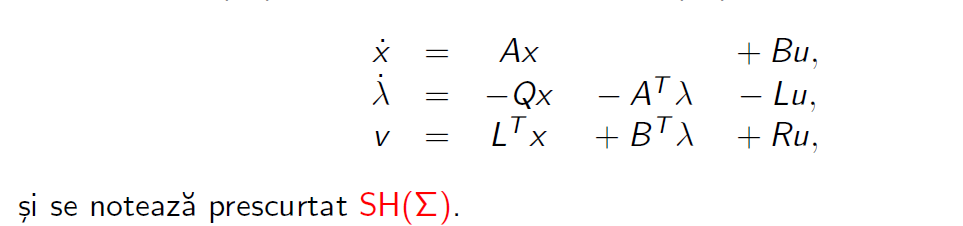

Pentru a vedea de ce scriem asa pe $N_{\Sigma }$

N_Sigma = [A zeros(4,4) B;
           -Q -A' -L;
           L' B' R]

N_Sigma =     1.0001    0.4227    0.0662    1.0061         0         0         0         0   -1.3218    0.9111    0.9298
   -1.6642   -1.6702    0.6524   -0.6509         0         0         0         0    0.9248    0.5946    0.2398
   -0.5900    0.4716    0.3271    0.2571         0         0         0         0    0.0000    0.3502   -0.6904
   -0.2781   -1.2128    1.0826   -0.9444         0         0         0         0   -0.0549    1.2503   -0.6516
   -8.6505    2.5629   -5.4559   -3.4250   -1.0001    1.6642    0.5900    0.2781   -0.0101    0.0038    0.0047
    2.5629   -4.5779    1.6240   -1.0902   -0.4227    1.6702   -0.4716    1.2128    0.0212   -0.0065   -0.0014
   -5.4559    1.6240   -4.9767   -5.4110   -0.0662   -0.6524   -0.3271   -1.0826    0.0050   -0.0083    0.0029
   -3.4250   -1.0902   -5.4110   -9.6404   -1.0061    0.6509   -0.2571    0.9444    0.0127    0.0101   -0.0030
    0.0101   -0.0212   -0.0050   -0.0127   -1.3218    0.9248    0.0000   -0.0549    2.5520   -0.6282  

## **Reamintire Fascicol Hamiltonian (Extins)**

M_Sigma = blkdiag(eye(4*2),zeros(3))

M_Sigma =      1     0     0     0     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0     0     0     0
     0     0     1     0     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0     0
     0     0     0     0     1     0     0     0     0     0     0
     0     0     0     0     0     1     0     0     0     0     0
     0     0     0     0     0     0     1     0     0     0     0
     0     0     0     0     0     0     0     1     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0


Ce facem cu asta? Aceste 2 matrici sunt folosite pentru a defini problema valorilor proprii generalizate: $N_{\Sigma } v={\mathrm{sM}}_{\Sigma } v$

[Nt, Mt, Qi, Zi] = qz(N_Sigma,M_Sigma) % putem pune 'real' pentru a tine real

Nt =   -2.7924 - 0.4462i   0.4075 + 1.2345i   3.5031 - 3.0305i  -5.4964 + 1.5537i   2.6692 + 2.7685i  -1.8557 + 1.8573i  -2.7830 - 1.0690i  -2.0395 + 1.1405i   0.5063 + 0.0860i   0.0363 - 0.0991i   0.2752 - 0.1291i
   0.0000 + 0.0000i  -3.2950 + 0.5265i   0.4792 + 6.2416i   0.6263 - 9.0398i   1.2471 + 1.1221i   4.2250 - 4.2931i   1.1468 - 2.8582i   3.4307 - 3.8816i  -0.3546 + 0.6207i  -0.1671 + 0.1422i  -0.4295 + 0.5007i
   0.0000 + 0.0000i   0.0000 + 0.0000i   3.6917 - 0.5898i  -1.0766 + 0.2159i  -1.6164 + 1.2987i  -4.3970 + 0.3657i  -0.2065 - 0.6413i  -1.8976 - 0.3701i   0.1484 + 0.7402i  -0.0431 + 0.1465i  -1.3235 + 0.1260i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   3.7307 + 0.5961i  -2.0625 + 0.8437i  -0.2297 + 2.5761i   1.1080 + 0.1794i   0.7978 + 1.1586i  -1.2708 - 0.1538i  -0.2451 + 0.0126i  -0.0962 + 0.7740i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   2.5333 + 0.0000i  -1.8139 + 0.0000i  -1.0248 + 0.0000i  -0.4784 + 0.0000i  -

Mt =    0.6995 + 0.0000i  -0.1144 - 0.0459i   0.0373 + 0.1098i   0.0503 + 0.0481i  -0.1209 - 0.1496i  -0.0171 - 0.0142i   0.0695 + 0.1093i  -0.0122 - 0.0020i   0.2107 + 0.4214i  -0.1614 - 0.1472i   0.3561 + 0.1621i
   0.0000 + 0.0000i   0.8255 + 0.0000i  -0.0341 + 0.0059i  -0.0484 + 0.1065i  -0.0891 - 0.0284i  -0.0032 - 0.0104i   0.0826 - 0.0054i   0.0086 - 0.0150i   0.3716 - 0.0999i  -0.0482 - 0.0866i  -0.1127 + 0.3423i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.9248 + 0.0000i  -0.1063 + 0.0105i  -0.0127 + 0.0077i  -0.0077 + 0.0014i  -0.0406 + 0.0106i  -0.0018 - 0.0038i  -0.1346 + 0.0046i  -0.2292 + 0.0956i  -0.1483 + 0.1716i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.9346 + 0.0000i  -0.0120 + 0.0069i  -0.0017 + 0.0044i  -0.0144 + 0.0232i   0.0066 + 0.0014i   0.0042 + 0.0794i  -0.1420 + 0.1275i  -0.2783 + 0.0727i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.9444 + 0.0000i  -0.0153 + 0.0000i   0.0537 + 0.0000i  -0.0043 + 0.0000i   

Qi =   -0.0932 - 0.2481i   0.1213 + 0.0403i   0.0618 + 0.0705i   0.2540 + 0.2198i  -0.0350 - 0.4999i   0.0864 + 0.0921i   0.3904 + 0.1980i   0.4901 + 0.3047i  -0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
  -0.2474 + 0.1014i  -0.0585 + 0.1304i   0.0375 + 0.0200i   0.0599 + 0.1474i  -0.6406 + 0.4160i   0.0437 + 0.0340i  -0.0962 + 0.3563i  -0.0452 + 0.3953i  -0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 - 0.0000i
  -0.4930 - 0.1993i   0.0172 - 0.1308i   0.0087 - 0.0715i  -0.2493 - 0.2348i   0.0925 + 0.0888i  -0.6097 + 0.2570i   0.2316 - 0.1547i  -0.0403 + 0.2094i  -0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i
   0.3826 + 0.3102i   0.2208 + 0.0014i   0.1206 + 0.0012i   0.4211 + 0.1687i  -0.1591 - 0.0628i  -0.3823 + 0.3389i   0.2422 - 0.1237i  -0.3522 + 0.0053i  -0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i
   0.5388 + 0.0000i  -0.1613 + 0.0000i  -0.3573 + 0.0000i  -0.3905 + 0.0000i  -0.3063 + 0.0000i  -0.3579 + 0.0000i   0.0062 + 0.0000i   0.4261 + 0.0000i  -

Zi =   -0.0652 + 0.1736i  -0.1822 - 0.1078i  -0.4776 + 0.1854i   0.4140 - 0.3297i   0.5787 + 0.0000i   0.0850 + 0.0000i  -0.1235 + 0.0000i   0.1443 + 0.0000i   0.0040 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0849 - 0.0282i  -0.0640 - 0.1086i   0.0276 + 0.1369i   0.2279 - 0.0111i  -0.1754 + 0.0000i  -0.8889 + 0.0000i  -0.1436 + 0.0000i   0.2509 + 0.0000i  -0.0061 + 0.0000i  -0.0034 + 0.0000i   0.0001 + 0.0000i
   0.0432 - 0.0493i   0.0207 - 0.0113i   0.0169 + 0.0712i   0.1179 - 0.0042i  -0.3615 + 0.0000i   0.3742 + 0.0000i  -0.1326 + 0.0000i   0.8292 + 0.0000i  -0.0004 + 0.0000i  -0.0016 + 0.0000i   0.0029 + 0.0000i
   0.1777 - 0.1538i   0.0103 - 0.1082i  -0.1981 + 0.2422i   0.4537 - 0.1706i  -0.4444 + 0.0000i   0.1079 + 0.0000i   0.5716 + 0.0000i  -0.2532 + 0.0000i  -0.0045 + 0.0000i  -0.0021 + 0.0000i  -0.0055 + 0.0000i
  -0.0245 + 0.3497i  -0.5018 - 0.3989i   0.0537 - 0.0569i  -0.1081 + 0.0444i  -0.1640 + 0.0000i   0.0565 + 0.0000i   0.0152 + 0.0000i  -0.0465 + 0.0000i  -

Ce se intampla aici? Aici se face Forma Schur generalizata, care imi cauta matricile $Q_i ,Z_i$ astfel incat $Q_i N_{\Sigma } Z_i =N_t$ si $Q_i M_{\Sigma } Z_i =M_t$, unde ambele $N_t ,M_t$ sunt superior triunghiulare

diag(Nt) ./ diag(Mt)

ans =   -3.9917 - 0.6378i
  -3.9917 + 0.6378i
   3.9917 - 0.6378i
   3.9917 + 0.6378i
   2.6824 + 0.0000i
  -2.6824 + 0.0000i
  -0.3455 + 0.0000i
   0.3455 + 0.0000i
      Inf + 0.0000i
     -Inf + 0.0000i
     -Inf + 0.0000i


Aici am calcualt Valorile Proprii Generalizate (V.P.G).

[Nt, Mt, Qi, Zi] = ordqz(Nt, Mt, Qi, Zi,'lhp') % Aici le ordonez "left half-plane"

Nt =   -2.7924 - 0.4462i   0.4075 + 1.2345i   1.1382 + 1.7564i  -0.8489 - 0.2446i   3.8049 - 5.2778i  -4.0146 + 1.4025i   3.7850 + 2.1786i  -2.0395 + 1.1405i   0.5063 + 0.0860i   0.0363 - 0.0991i   0.2752 - 0.1291i
   0.0000 + 0.0000i  -3.2950 + 0.5265i   1.3071 - 0.0564i   0.4595 - 0.9475i  -0.2488 + 7.6444i  -1.1969 - 9.8211i  -0.5839 + 3.2141i   3.4307 - 3.8816i  -0.3546 + 0.6207i  -0.1671 + 0.1422i  -0.4295 + 0.5007i
   0.0000 + 0.0000i   0.0000 + 0.0000i  -2.5415 + 0.0000i  -0.3491 + 0.0000i   4.3887 + 0.2597i   0.0422 + 3.4019i   1.3205 + 0.0000i  -1.9913 + 0.0000i  -0.5956 + 0.0000i  -0.7127 + 0.0000i  -1.3630 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.3409 + 0.0000i  -0.2020 - 0.4096i  -0.5146 - 0.1302i   1.4142 - 0.0000i   0.2778 + 0.0000i   0.3770 - 0.0000i  -0.3100 - 0.0000i   0.6563 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   3.7984 - 0.6069i  -0.6226 + 0.1718i  -0.7645 + 1.4501i  -0.9624 - 0.6498i   

Mt =    0.6995 + 0.0000i  -0.1144 - 0.0459i   0.0117 - 0.0012i   0.0196 + 0.0601i   0.0320 + 0.1384i   0.0293 + 0.0816i  -0.1226 - 0.1603i  -0.0122 - 0.0020i   0.2107 + 0.4214i  -0.1614 - 0.1472i   0.3561 + 0.1621i
   0.0000 + 0.0000i   0.8255 + 0.0000i  -0.0126 + 0.0174i   0.0627 - 0.0287i  -0.0272 + 0.0026i  -0.0410 + 0.1101i  -0.1020 - 0.0207i   0.0086 - 0.0150i   0.3716 - 0.0999i  -0.0482 - 0.0866i  -0.1127 + 0.3423i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.9475 + 0.0000i  -0.0132 + 0.0000i  -0.0486 - 0.0547i  -0.0673 - 0.0342i  -0.0367 + 0.0000i  -0.0029 - 0.0000i  -0.0437 + 0.0000i  -0.2775 + 0.0000i  -0.1040 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.9868 + 0.0000i  -0.0214 - 0.0005i   0.0008 - 0.0167i   0.0305 - 0.0000i  -0.0042 + 0.0000i  -0.1487 + 0.0000i  -0.0346 + 0.0000i   0.0341 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.9516 + 0.0000i  -0.0729 + 0.0345i   0.0280 - 0.0020i  -0.0004 - 0.0044i  -

Qi =   -0.0932 - 0.2481i   0.1213 + 0.0403i   0.0618 + 0.0705i   0.2540 + 0.2198i  -0.0350 - 0.4999i   0.0864 + 0.0921i   0.3904 + 0.1980i   0.4901 + 0.3047i  -0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
  -0.2474 + 0.1014i  -0.0585 + 0.1304i   0.0375 + 0.0200i   0.0599 + 0.1474i  -0.6406 + 0.4160i   0.0437 + 0.0340i  -0.0962 + 0.3563i  -0.0452 + 0.3953i  -0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 - 0.0000i
  -0.1360 - 0.0000i  -0.6498 - 0.0000i   0.2029 - 0.0000i  -0.1569 + 0.0000i   0.0132 + 0.0000i  -0.6045 + 0.0000i   0.3574 + 0.0000i   0.0135 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i
  -0.0066 + 0.0000i  -0.1762 - 0.0000i  -0.2752 + 0.0000i   0.3222 + 0.0000i   0.0707 - 0.0000i  -0.3543 + 0.0000i  -0.6457 + 0.0000i   0.4918 - 0.0000i  -0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 - 0.0000i
  -0.5056 - 0.2520i   0.4453 - 0.1963i  -0.1337 - 0.0399i  -0.1858 - 0.3310i   0.1055 + 0.1010i  -0.3484 + 0.2948i   0.0200 - 0.0883i  -0.0403 + 0.2028i   

Zi =   -0.0652 + 0.1736i  -0.1822 - 0.1078i  -0.1248 - 0.0000i  -0.0399 - 0.0000i  -0.5047 + 0.2443i   0.3487 - 0.4094i   0.5284 + 0.0000i   0.1443 + 0.0000i   0.0040 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0849 - 0.0282i  -0.0640 - 0.1086i  -0.6113 - 0.0000i  -0.1680 - 0.0000i   0.4705 + 0.2413i   0.2798 + 0.3505i   0.1747 + 0.0000i   0.2509 + 0.0000i  -0.0061 + 0.0000i  -0.0034 + 0.0000i   0.0001 + 0.0000i
   0.0432 - 0.0493i   0.0207 - 0.0113i   0.1928 - 0.0000i  -0.2670 + 0.0000i  -0.1205 + 0.0339i   0.0517 - 0.0961i  -0.4141 + 0.0000i   0.8292 + 0.0000i  -0.0004 + 0.0000i  -0.0016 + 0.0000i   0.0029 + 0.0000i
   0.1777 - 0.1538i   0.0103 - 0.1082i  -0.1441 - 0.0000i   0.3378 - 0.0000i  -0.1388 + 0.3557i   0.4678 - 0.1317i  -0.5932 + 0.0000i  -0.2532 + 0.0000i  -0.0045 + 0.0000i  -0.0021 + 0.0000i  -0.0055 + 0.0000i
  -0.0245 + 0.3497i  -0.5018 - 0.3989i   0.0280 + 0.0000i  -0.0133 + 0.0000i   0.0465 - 0.0761i  -0.1012 + 0.0413i  -0.1710 + 0.0000i  -0.0465 + 0.0000i  -

diag(Nt) ./ diag(Mt)

ans =   -3.9917 - 0.6378i
  -3.9917 + 0.6378i
  -2.6824 + 0.0000i
  -0.3455 + 0.0000i
   3.9917 - 0.6378i
   3.9917 + 0.6378i
   2.6824 + 0.0000i
   0.3455 + 0.0000i
      Inf + 0.0000i
     -Inf + 0.0000i
     -Inf + 0.0000i


Cu asta calculez $2n+m$ V.P.G, primele n fiind din ${\mathbb{C}}_-$, urmatoarele n din ${\mathbb{C}}_+$, iar ultimele m din $\left\lbrace \infty \right\rbrace$

svd(Zi(1:4,1:4))

ans =     0.6978
    0.4904
    0.2905
    0.1601


ans(1) / ans(4)

ans = 4.3586

Aici verific daca $Z_1 \;\mathrm{sau}\;V_1$ este inversabil

Xs_qz = Zi(5:8,1:4) / Zi(1:4,1:4);


$$X=Z_2 Z_1^{-1} =V_2 V_1^{-1}$$


Xs_qz = real(Xs_qz);
Xs_qz = 1/2 * (Xs_qz + Xs_qz') % am luat partea reala si am simetrizat

Xs_qz =     3.1361   -0.5479    1.1767    0.9890
   -0.5479    1.1648    0.0516   -0.4298
    1.1767    0.0516    3.5502    1.0808
    0.9890   -0.4298    1.0808    2.2348


X

X =     3.1361   -0.5479    1.1767    0.9890
   -0.5479    1.1648    0.0516   -0.4298
    1.1767    0.0516    3.5502    1.0808
    0.9890   -0.4298    1.0808    2.2348


disp(Xs_qz - X) % se vede ca merge

   1.0e-14 *

    0.0888    0.0777    0.2665    0.2442
    0.0777   -0.1554    0.2727    0.1610
    0.2665    0.2727   -0.0888    0.1332
    0.2442    0.1610    0.1332    0.0888



Fs_qz = Zi(9:11,1:4) / Zi(1:4,1:4);


$$F=Z_3 Z_1^{-1} =V_3 V_1^{-1}$$


Fs_qz = real(Fs_qz);
Fs_qz = -Fs_qz% Fac aia cu reactie pozitiva

Fs_qz =    -1.6310    0.7440    0.0163   -0.1556
    1.3729    0.0783    1.8140    1.7779
    1.0694   -0.1488   -1.5432   -1.0619


disp(Fs_qz - F)

   1.0e-14 *

   -0.0888    0.0666   -0.1044   -0.0611
    0.1332         0    0.1554   -0.0888
   -0.2442   -0.1110    0.1110   -0.0666

